This file is for exam.

close all;
clear all;
clc;

mW = 1e3; % W to mW
kHz = 1e3;
MHz = 1e6;
GHz = 1e9;
km = 1e3;
c = 3e8;    % speed of light, m/s
k_B = 1.38e-23;          % Boltzmann’s constant, J/K

EE609 hw3.5 Pb = qfunc(sqrt(Sb*(1-rho)/N0))

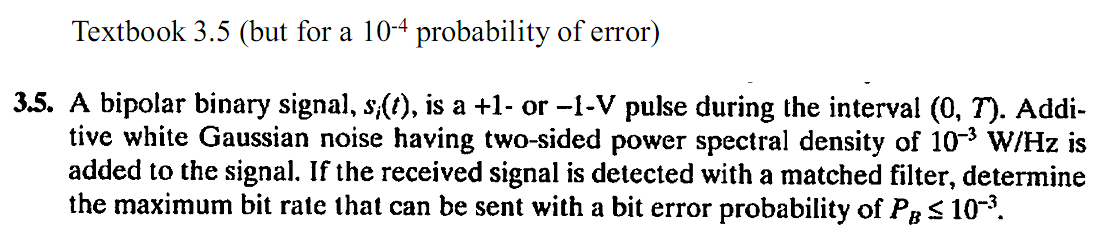

%{
flag = 1;
if flag ==1
syms E_b;
else
E_b = 0:0.0001:0.008;
end
P_B = 1e-4;
rho = -1;
N = 1e-3; % two-sided power spectral density
N_0 = N*2; % one-sided power spectral density
A = 1;
% y = qfunc(sqrt(E_b.*(1-rho)./N_0))-P_B
y = 0.5.*erfc(sqrt(E_b.*(1-rho)./N_0./2))-P_B

if flag ==1
y1=matlabFunction(y);
[E_b]=fzero(y1,0.007);
% E_b = solve(y == 0,E_b)
else
figure,
plot(E_b,y)
end

S = A^2;
syms R;
R = solve(E_b == S./R,R)
R=double(R)
%}

EE609 hw3.13 for unipolar RZ, rho = 0, Eb = 0.5*A^2*T; for bipolar RZ, rho = -1, Eb = A^2*T

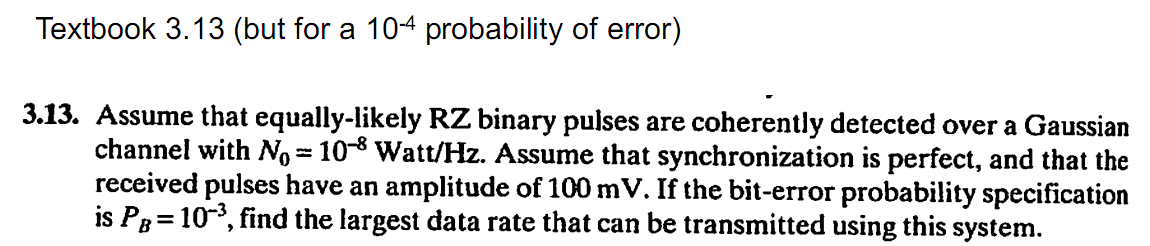

%{
P_B = 1e-4;
rho = 0;
N_0 = 1e-8; % one-sided power spectral density
A = 0.1;
switch rho
    case 0
        S = A^2/2;
    case -1
        S = A^2;
end

syms E_b;
E_b1 = 0:N_0/10:N_0*10;

% y = qfunc(sqrt(E_b.*(1-rho)./N_0))-P_B
y = 0.5.*erfc(sqrt(E_b.*(1-rho)./N_0./2))-P_B
y_p = 0.5.*erfc(sqrt(E_b1.*(1-rho)./N_0./2))-P_B;
figure,
plot(E_b1,y_p)
x = find(abs(y_p)==min(abs(y_p)))
y1=matlabFunction(y);
[E_b]=fzero(y1,x*N_0);
% E_b = solve(y == 0,E_b)

syms R;
R = solve(E_b == S./R,R)
R=double(R)
%}

%{
Pb = 1e-4;
N0 = 1e-10;
A = 1;
Eb = qfuncinv(Pb)^2*N0/2;
T = Eb/A^2;
Rb = 1/T;

%}

quiz-1 requirements for distortionless transmission through a linear system

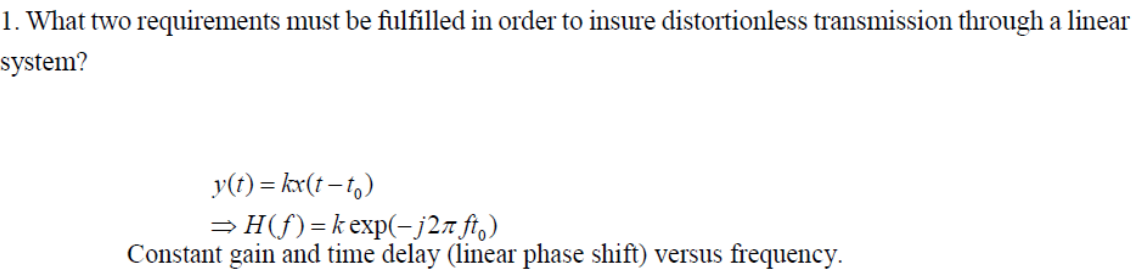

%{
H(f) = K*exp(-1j*2*pi*f*t0); % K and t0 are constant
%}

Rs = 1/T; symbols/s

for double side bandwidth,

W=(1+r)*Rs, r=(W-W0)/W0, W0 is filter bandwidth, W is system bandwidth, the filter is raised cosine filter

if r = 0, no filter, no ISI, so W*T=1;

N_DSB = N0/2

for single side bandwidth or based band,

W=(1+r)*Rs/2, r=(W-W0)/W0, W0 is filter bandwidth, W is system bandwidth, the filter is raised cosine filter

for r=0, W>Rs/2, nyquist pulse, W is the minimum system bandwidth, bandwidth efficiency: 2 symbols/s/Hz, precise sampling at nT

EE609 hw4-1 equalization: zero-forcing solution

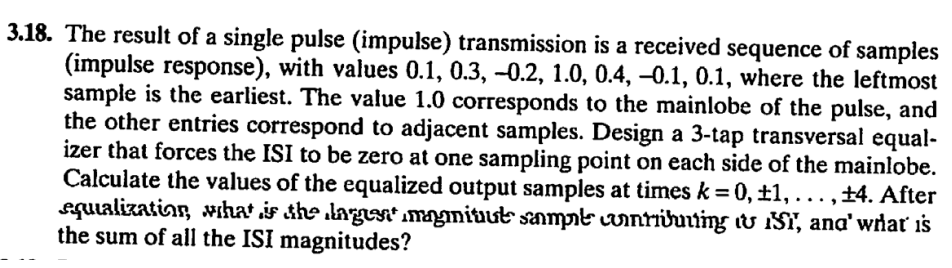

where tap = 5

%{
tap = 5;
% x = [0.1 0.3 -0.2 1.0 0.4 -0.1 0.1];
x = [0.1 0.2 0.3 0.3 0.4 1.0 0.4 0.1 0.3 0.1 0.1];
n = ceil(length(x)/2);
% X = [x(n) x(n-1) x(n-2) x(n-3) 0;...
%     x(n+1) x(n) x(n-1) x(n-2) x(n-3);...
%     x(n+2) x(n+1) x(n) x(n-1) x(n-2);...
%     x(n+3) x(n+2) x(n+1) x(n) x(n-1);...
%     0 x(n+3) x(n+2) x(n+1) x(n)];
n1 = floor(tap/2);
Xc = [x,zeros(1,length(x)-1)];
Xr = [x(1),zeros(1,length(x)-1)];
X1 = toeplitz(Xc, Xr);
X = X1(length(x)-n1:length(x)+n1,n-n1:n+n1);
Z = zeros(tap, 1);
Z(ceil(tap/2)) = 1;
C = X\Z % =inv(X)*Z
z_out = conv(C,x');
z1 = sort(abs(z_out),'descend');
ISI_max = z1(2)
ISI = sum(abs(z_out))-z1(1)
%}

EE609 hw4-2 equalization: MMSE minimum mean square error solution

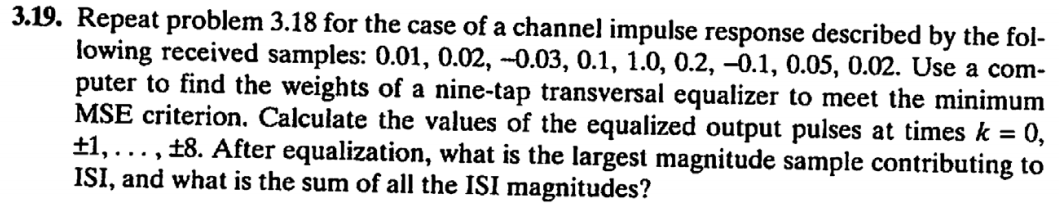

where tap = 7

%{
tap = 7;
k = 8; % 题中给的所求输出，一共2*k+1位，中心是第9位
x = [0.01 0.02 -0.03 0.1 1.0 0.2 -0.1 0.05 0.02];
% x = [0.1 0.2 0.3 0.3 0.4 1.0 0.4 0.1 0.3 0.1 0.1];
N = floor(tap/2);
Xc = [x,zeros(1,4*N+1-length(x))];
Xr = [x(1),zeros(1,2*N+1-1)]; % 2*N+1
X = toeplitz(Xc, Xr);
Z = zeros(length(Xc), 1);
Z(ceil(length(Xc)/2)) = 1;
C = (X'*X)\(X'*Z) % inv(X'*X)*(X'*Z)
xi = [zeros(1,k+1-tap) Xc]; % in professor's PPT，为了将中心移到第九位，因为一共17位输出
z_out = conv(C,xi');
z1 = sort(abs(z_out),'descend');
ISI_max = z1(2)
ISI = sum(abs(z_out))-z1(1)
%}

%{
% ???????????????????
tap = 5;
x = [0.1 0.2 0.3 0.3 0.4 1.0 0.4 0.1 0.3 0.1 0.1];
N = floor(tap/2);
% Xc = [x(1:9)];
Xc = x(2:10);
% Xc = [x,zeros(1,4*N+1-length(x))];
Xr = [x(2),zeros(1,2*N+1-1)]; % 2*N+1
X = toeplitz(Xc, Xr);
Z = zeros(length(Xc), 1);
Z(ceil(length(Xc)/2)) = 1;
C = (X'*X)\(X'*Z) % inv(X'*X)*(X'*Z)
% x = [0 0 Xc]; % in professor's PPT
z_out = conv(C,x');
%}

EE609 hw6-2 noise figure and noise temperature

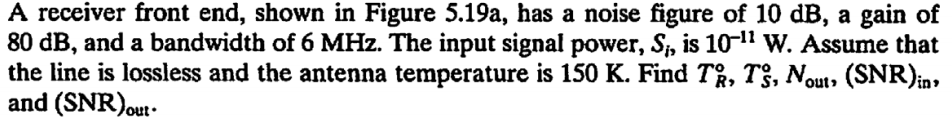

where Ta=660K,W=2.5MHz

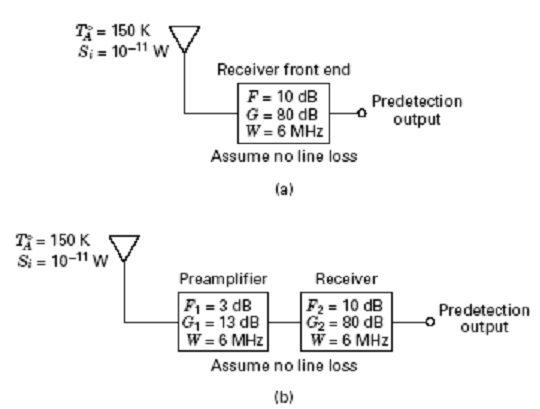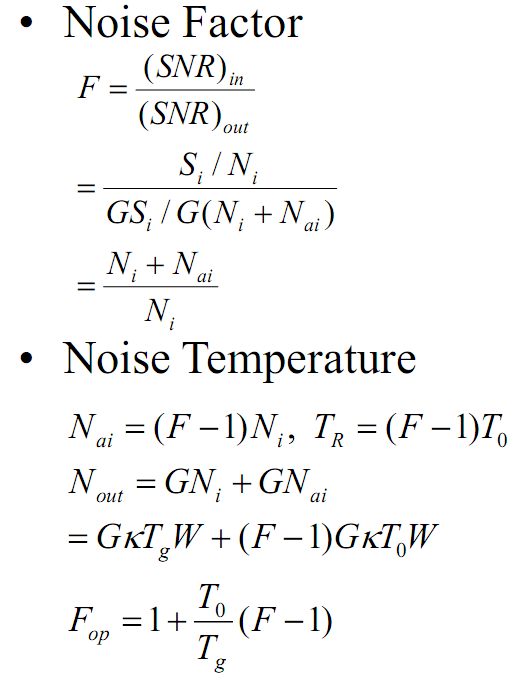

%{
num_preamplifier = 0; % the number of preamplifier
NF = zeros(2,num_preamplifier+1);
NF(1,1) = 0; % Noise factor of amplifier 1
% NF(1,2) = 0; % Noise factor of amplifier 2
% NF(1,n) = 0; % Noise factor of amplifier n
NF(2,1) = 14; % db, Noise figure of amplifier 1
% NF(2,2) = 14; % db, Noise figure of amplifier 2
% NF(2,n) = 0; % db, Noise figure of amplifier n
G(1,1) = 60; % db, gain of amplifier 1
% G(1,2) = 60; % db, gain of amplifier 2
% G(1,n) = 80; % db, gain of amplifier n
W = 6*MHz;
Si = 1e-11; % W, the power of input signal
Tg = 190; % the temperature of the source
Ta = Tg; % the temperature of the antenna

for i = 1:num_preamplifier+1
    if NF(1,i)==0
        NF(1,i) = 10^(NF(2,i)/10); % noise factor
    end
end
for i = 1:num_preamplifier+1
    G(2,i) = 10^(G(1,i)/10);
end
Gsum = prod(G(2,:));
Fcomp = NF(1,1);
if num_preamplifier ~= 0
    for i = 1:num_preamplifier
        Fcomp = (NF(1,i+1)-1)/prod(G(2,1:i))+Fcomp; % F = F1+(F2-1)/G(2,1)+(F3-1)/(G(2,1)*G(2,2))+...+(Fn-1)/(G(2,1)*G(2,2)*...*G(2,n-1));
    end
end
Tr = zeros(1,num_preamplifier+1);
for i = 1:num_preamplifier+1
        Tr(i) = (NF(1,i)-1)*290; % the effective noise temperature of the receiver (or network), Tr=(F-1)T0
end
Tcomp = Tr(1);
if num_preamplifier ~= 0
    for i = 1:num_preamplifier
        Tcomp = Tr(1,i+1)/prod(G(2,1:i))+Tcomp; % Tcomp = Tr1+Tr2/G(2,1)+Tr3/(G(2,1)*G(2,2))+...+Trn/(G(2,1)*G(2,2)*...*G(2,n-1));
    end
end
Ts = Ta + Tcomp % the system temperature
Ni = k_B*Ta*W; % the noise power at the amplifier input
Nout = Gsum*k_B*Ts*W
SNRin = Si/Ni;
SNRin_db = db(SNRin,'p')
Sout = Gsum*Si;
SNRout = Sout/Nout;
SNRout_db = db(SNRout,'p')
%}

noise figure and noise temperature for lossy line

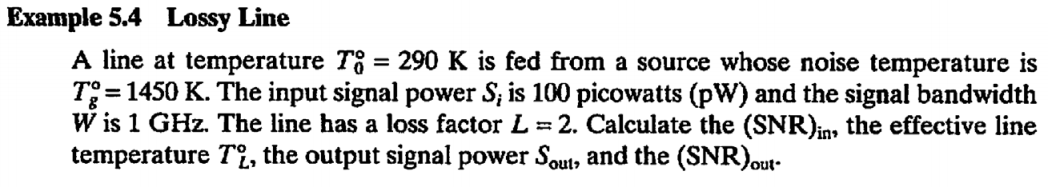

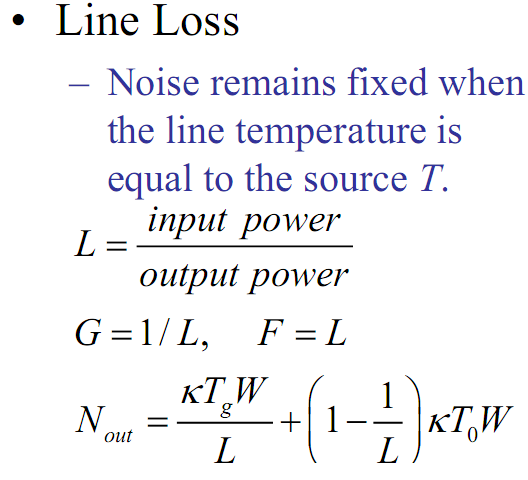

%{
W = 1*GHz; % signal bandwidth
Tg = 1450; % the temperature of the source
T0 = 290; %
Si = 100e-12; % W, the input signal, 1pW = 1e-12W
L = 2; % loss factor

Ni = k_B*Tg*W; %
SNRin = Si/Ni;
SNRin_db = db(SNRin,'p'); %
TL = (L-1)*T0; %
Ts = Tg+TL;
Sout = Si/L;
Nout = 1/L*k_B*Ts*W;
SNRout = Sout/Nout;
SNRout_db = db(SNRout,'p');
%}

EE609 hw6-3 calculate the link budget

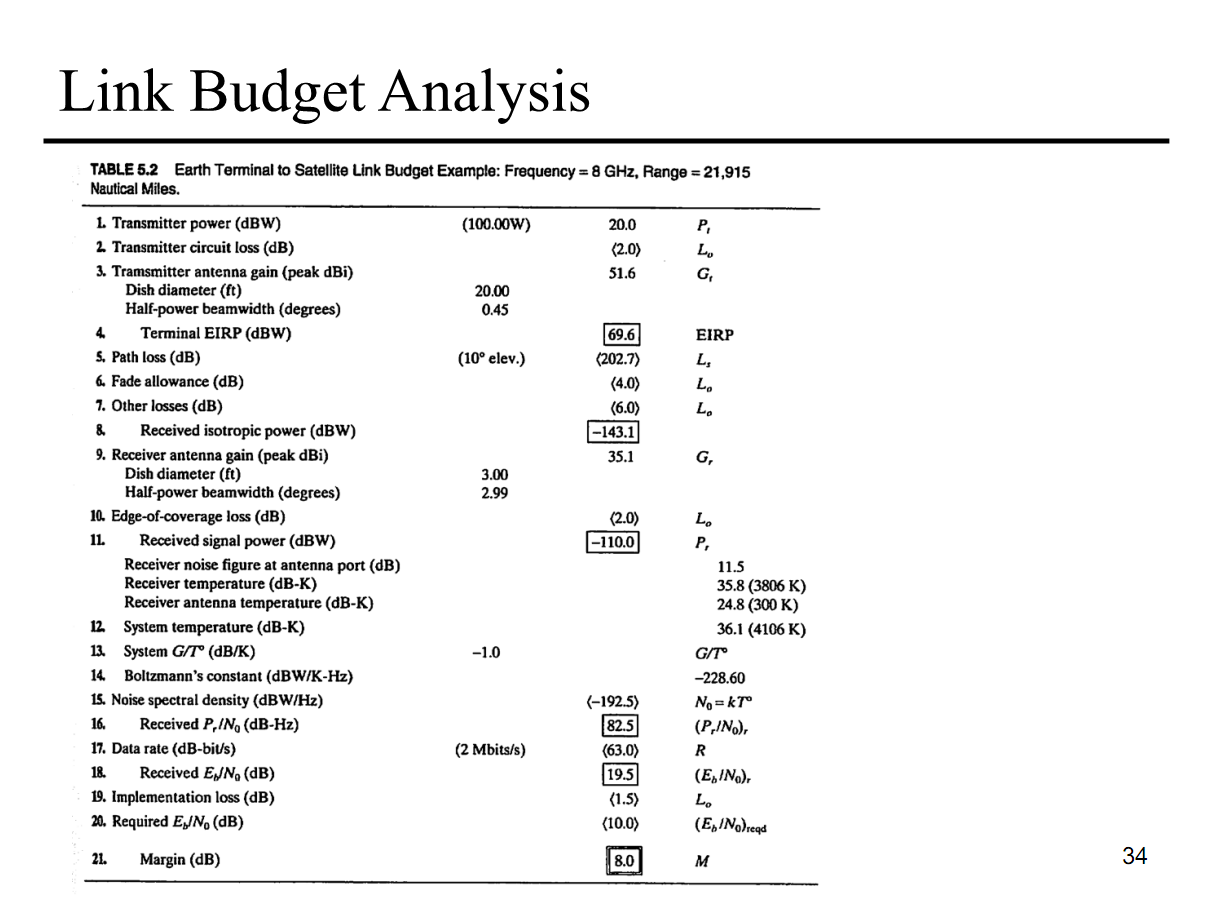

where TX = 25W, Tr = 6000K, R = 8Mbps

%{
f_carrier = 8*GHz;    % carrier frequency, Hz
if f_carrier == 'GSM'
    f_carrier = 900*MHz;
end
TX = 25; % transmitter power
TX_unit = 'w'; % W or mW or dbm or dbW
if TX ~= 'ans'
    switch TX_unit
        case 'w'
            TX = db(TX*mW,'p'); % dbm
        case 'mw'
            TX = db(TX,'p'); % dbm
        case 'dbw'
            TX = TX+30; % dbm
        case 'dbm'
            TX = TX;
    end
end
L0 = 2; % transmitter circuit loss
TX_gain = 51.6;% db, transmitter antenna gain
EIRP = TX-L0+TX_gain % dbm

d = 21915*1.852*km; % 1 nautical mile = 1.852*km
Ls = db((c/f_carrier/(4*pi*d))^2,'p'); % path loss
L1 = 4; % db, fade allowance
L2 = 6; % db, other losses
R_iso = EIRP+Ls-L1-L2 % dbm, received isotropic power

RX_gain = 35.1;% db, receive antenna gain
L3 = 2; % db, edge of coverage loss
Pr = R_iso+RX_gain-L3 % dbm, received signal power

NF = 11.5; % db, receiver noise figure
% Tr = 290*(10^(NF/10)-1); % K, receiver temperature
Tr = 6000;
Ta = 300; % K, receiver antenna temperature
Ts = Ta+Tr; % K, system temprature
N0 = db(k_B*Ts,'p')+30; % dbm/Hz, noise specture density
PrN0 = Pr-N0 % db, received Pr/N0

R = 8e6; % bits/s, data rate
EbN0 = PrN0-db(R,'p') % db, Eb=S/R=Pr/R

L4 = 1.5; % db, implentation loss
EbN0_req = 10; % db, required Eb/N0
M = EbN0-L4-EbN0_req % margin

P_iso = (lamda/(4*pi*d))^2*P_TX, P_RX is isotropic,

A_iso = lamda^2/(4*pi),

A_RX_e = lamda^2/(4*pi)*G_RX, A_RX_e is the effective area of receiving antenna

%}

EE609 hw5-1 the probability of errior

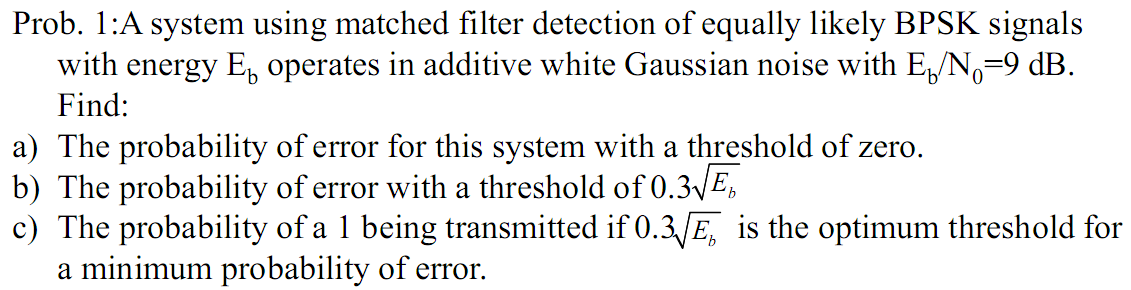

,   

%{
EbN0_db = 9; % db,
EbN0 = 10^(EbN0_db/10);

% a)
p = 0.5; % p(1)=p(0)=0.5
pe = qfunc(sqrt(2*EbN0)); % for BPSK
% b)
syms Eb r_th N0;
r_th = 0.3*sqrt(Eb);
% r_th = N0/(4*sqrt(Eb))*log((1-p)/p)
% pe = p*qfunc((sqrt(Eb)-r_th)/sqrt(N0/2))+(1-p)*qfunc((sqrt(Eb)+r_th)/sqrt(N0/2))
% y=subs(pe,Eb/N0,EbN0);
% y1 = double(y)

% c)

%}

EE609 hw5-2 Es/N0, Eb/N0

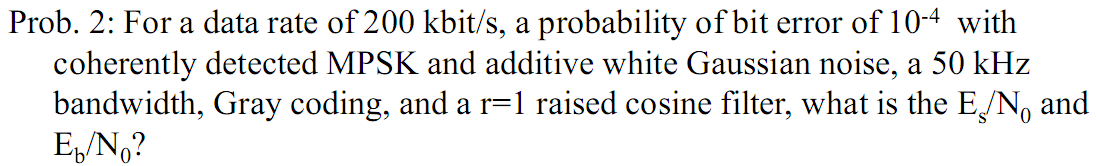

%{
R = 150e3; % bits/s, data rate
r = 0.5;

W=(1+r)*Rs, r=(W-W0)/W0, W0 is filter bandwidth, W is system bandwidth, the filter is raised cosine filter

W = 75e3; % Hz,
Pb = 1e-5;
syms Rs;
Rs = solve(W == (1+r)*Rs,Rs); % W_DSB = (1+r)*Rs
Rs = double(Rs);
m = R/Rs;
M = 2^m;

for MPSK + GreyCode, Page261

Pb = Pe/log2(M)

Pe = m*Pb;

for coherent detected, MPSK, P255

Pe = 2*qfunc(sqrt(2*Es/N0)*sin(pi/M))

x = qfuncinv(Pe/2);
syms EsN0;
EsN0 = solve(x == sin(pi/M)*sqrt(2*EsN0),EsN0);
EsN0 = double(EsN0);
EsN0_db = db(EsN0,'p');
EbN0 = EsN0/m;
EbN0_db = db(EbN0,'p');
%}

EE609 hw5-2 BER for modulation

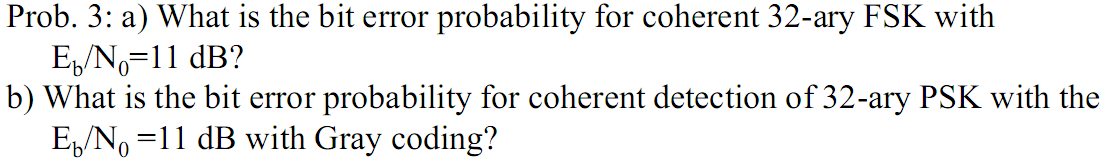

%{
M = 8;
m = log2(M
EbN0_db = 16; % db,
EbN0 = 10^(EbN0_db/10);
EsN0 = log2(M)*EbN0;
Pe = (M-1)*qfunc(sqrt(EsN0)); % Es = Eb*log2(M), for coh-detected MFSK, Page256
Pb = M/2/(M-1)*Pe; % for M- orthogonal, it works on coh-MFSK, because MFSK is a kind of orthogonal modulation, Page258

% Pe = 2*qfunc(sqrt(2*EsN0)*sin(pi/M)); % for coherent detected, MPSK, P255
% Pb = Pe/m; % for MPSK + GreyCode, Page261

% Pe = 2*qfunc(sqrt(2*EsN0)*sin(pi/(sqrt(2)*M))); % for differentially-coh-det MDPSK, Page256
% Pe = (M-1)/2*exp(-0.5*EsN0); % for none coh/coh-detected ortho MFSK, Page258

% Pb = qfunc(sqrt(EbN0)); % for coh-det binary ortho FSK, when MFSK, M=2, Pb = Pe, Page239
% Pb = qfunc(sqrt(2*EbN0)); % for coh-det BPSK antipodal Page237, =QPSK Page250
% Pb =  2*qfunc(sqrt(2*EbN0))*(1-qfunc(sqrt(2*EbN0))); % for coh-det BPSK differentially encode PSK Page238
% Pb = 1/2*exp(-0.5*EbN0); % for none-coh-det ortho FSK Page242, none-coh MFSK , Page258
% Pb = 1/2*exp(-EbN0); % for differentially-coh-det of differentially encoded PSK = DPSK, Page244
%}

quiz-1 bandwidth efficiency

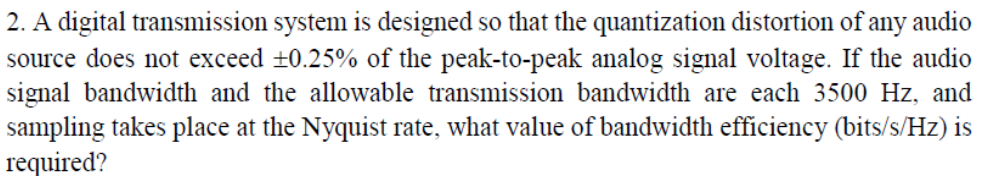

%{
p = 0.25e-2;
l = ceil(log2(1/(2*p)));
W = 3500; % Hz, system bandwidth
fm = 3500;
fs = 2*fm; % symbols/s, sampling rate is nyquist rate
RW = l*fs/W; % bits/s/Hz, Rb/W, bandwidth efficiency
%}

quiz-1 EbN0 Pb R

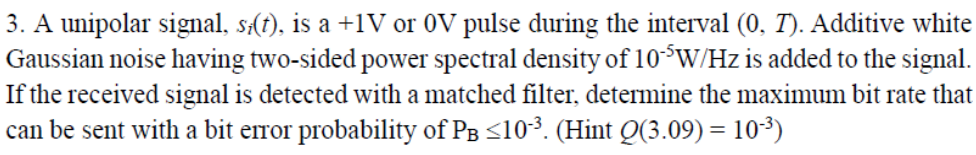

Pb = qfunc(sqrt(Ed/2*N0)) = qfunc(sqrt(Eb*(1-p)/N0)), for unipolar, p = 0; for bipolar, p = -1

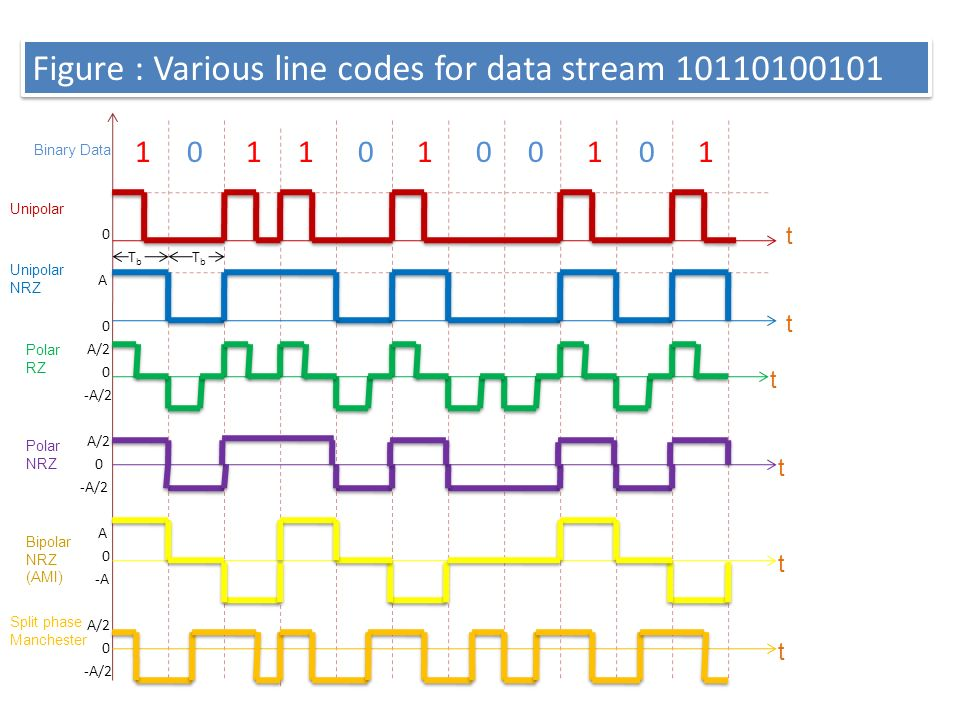

%{
N = 1e-3; % two-side power specture density
N0 = 2*N; % N_DSB = N0/2,
Pb = 1e-4;
A = 1;
x = qfuncinv(Pb); % sqrt(Eb/N0)
% EbN0 = x^2; % qfunc(sqrt(Eb*(1-p)/N0)), for unipolar, p = 0; for bipolar, p = -1
EbN0 = x^2/2; % qfunc(sqrt(Eb*(1-p)/N0)), for bipolar, p = -1
Eb = N0*EbN0;
syms R;
% R = solve(Eb == 0.5*A^2/R,R); % for unipolar, Eb = A^2*T/2, R = 1/T
R = solve(Eb == A^2/R,R); % for bipolar, Eb = A^2*T, R = 1/T
R = double(R); % bits/s
%}

quiz-1 SNR EbN0

%{
SNR = 16; % db, S/N
R = 20e3; % bits/s
W = 40e3; % Hz
EbN0 = SNR+db(W,'p')-db(R,'p'); % Eb/N0 = (S/R)/(N/W) = SNR*W/R = SNR+W_db-R_db
%}

EE609 hw2-1 quantization

%{
l = 5; % bits/sample
L = 2^l; % quantization levels
%}

EE609 hw2-2 quantization

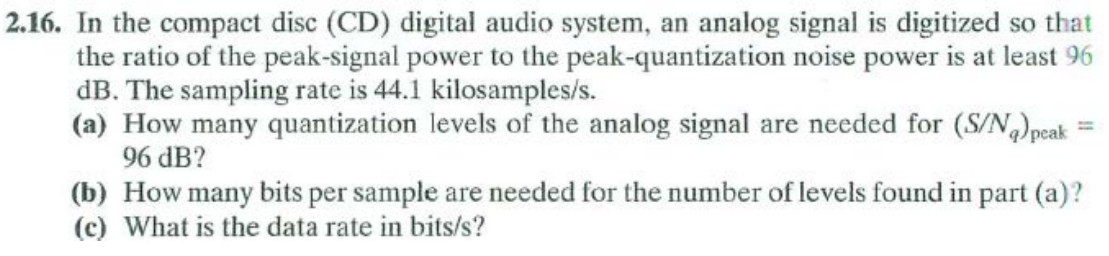

solution:

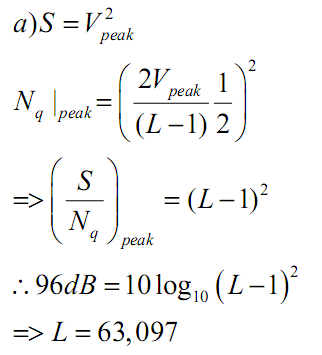

(S/N)ave = 3*L^2, 见笔记， Page101 in text book

%{

% L = 63097; % quantization levels
L = sqrt(10^(26/10)/3);
% Rs = 44.1e3; % samples/s
l = ceil(log2(L)); % bits/sample
% Rb = l*Rs;
W = 30*kHz; % Hz, system bandwidth
fm = 4000;
fs = 2*fm; % symbols/s, sampling rate is nyquist rate
RW = l*fs/W; % bits/s/Hz, Rb/W, bandwidth efficiency
%}

EE609 hw1-1 

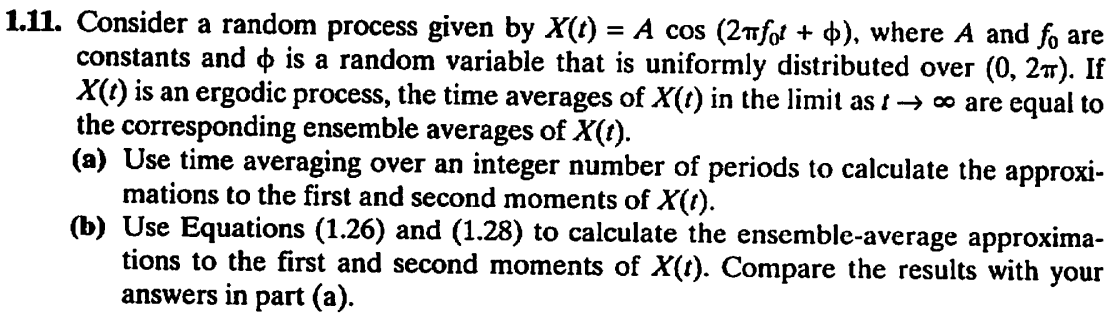

solution:

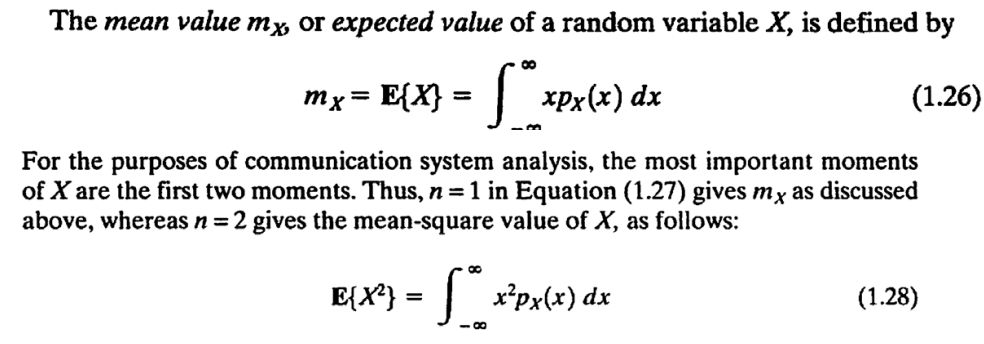

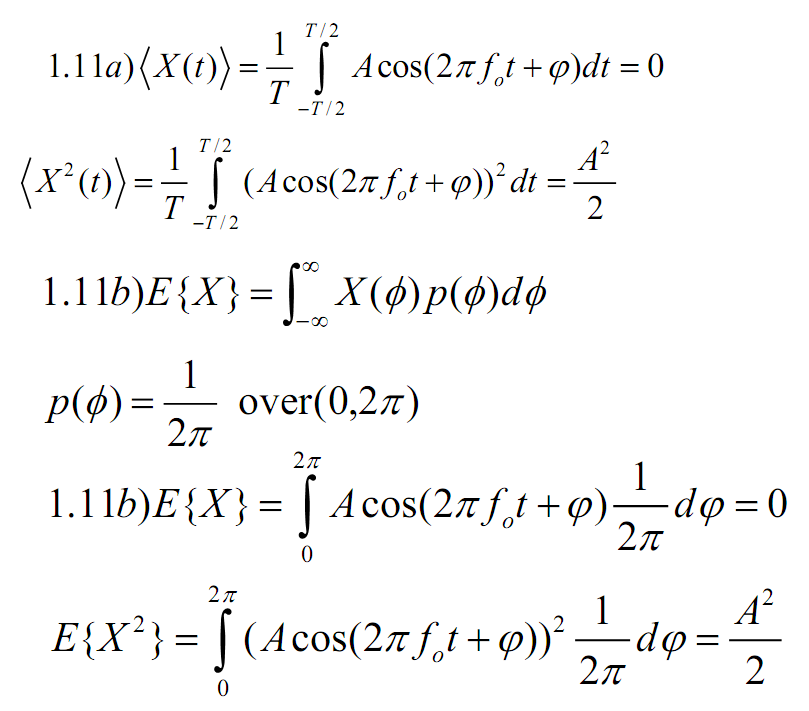

EE609 hw1-2

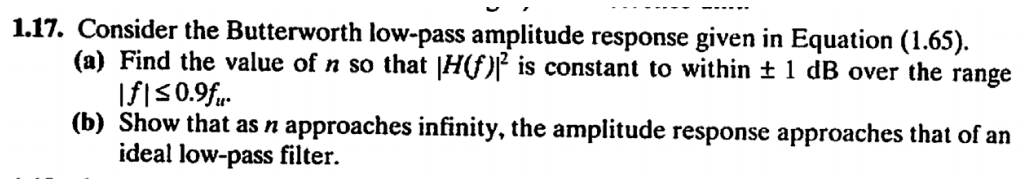

%{

syms n;
f_fu = 0.9; % f/fu
n = solve(-1 == 10*log10(1/sqrt(1+f_fu^(2*n))^2),n); % H(f) is a decreased function as shown in figure 1.14 in text book, and H(0) = 0,
                                                     % so, for f>0, H(f)<1
n = double(n)
n = ceil(n)
%}

Hamming Weight: the number of "1" in the code words

Hamming Distance: the number of different bits in two codes

Error detection: 

Error correcting: 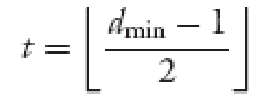

cyclic codes

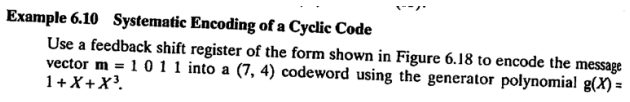

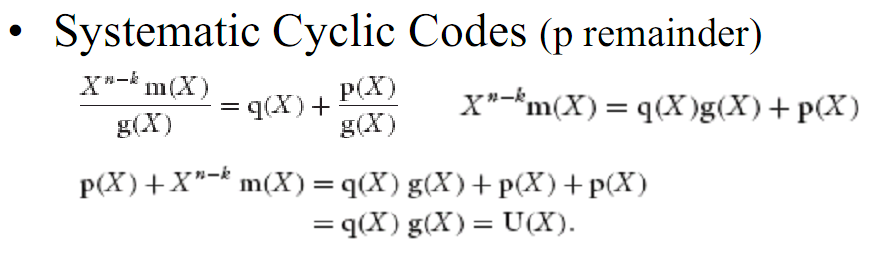

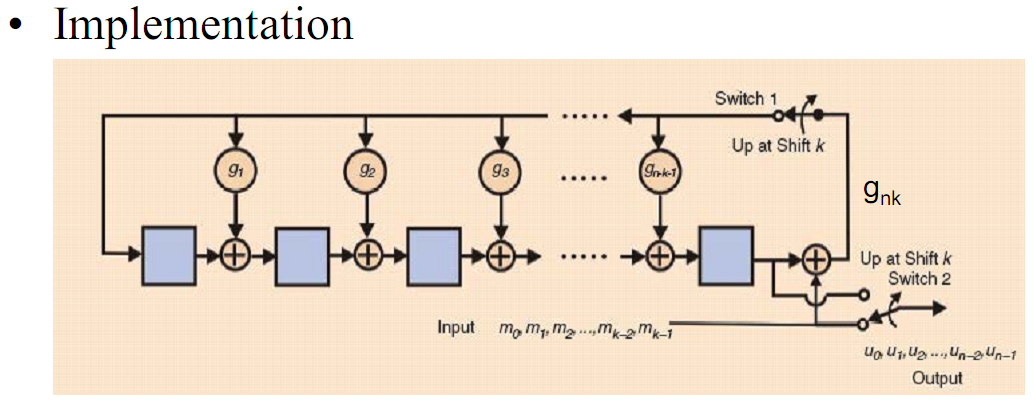

%{
n = 7; % 传递码的个数
k = 4; % 信息码的个数
syms x;
gX = 1+x+x^3 % g(X)
m = [1 0 1 1]; % m(X)的系数，由低到高
mX = poly2sym(fliplr(m)) % 将m翻转变为由高到低
X_mX = expand(x^(n-k)*mX) % X^(n-k)*m(X)=q(X)g(X)+p(X)
coef_X_mX = sym2poly(X_mX);
coef_gX = sym2poly(gX);
[coef_q,coef_p]=deconv(coef_X_mX,coef_gX); %q是商，r是余数。数组从后到前表示从〇次项到各高次项的系数
coef_qX = mod(coef_q,2);
coef_pX = mod(coef_p,2);
pX = poly2sym(coef_pX)
uX = X_mX+pX
u_out = fliplr(sym2poly(uX)) % 输出序列
% % % % % % % % % % H = (s^2*a1+a2*s+a1*a2*s+a2^3-a2*s^2)/(s^3*a1-a2*s+a1*a2^2*s+a1^3-a2*s^2)
% % % % % % % % % % [N,D]=numden(H) % 取分子分母
% % % % % % % % % % res1=fliplr(coeffs(N,s)) % fliplr左右翻转
% % % % % % % % % % res2=fliplr(coeffs(D,s))
%}

convolutional encoder

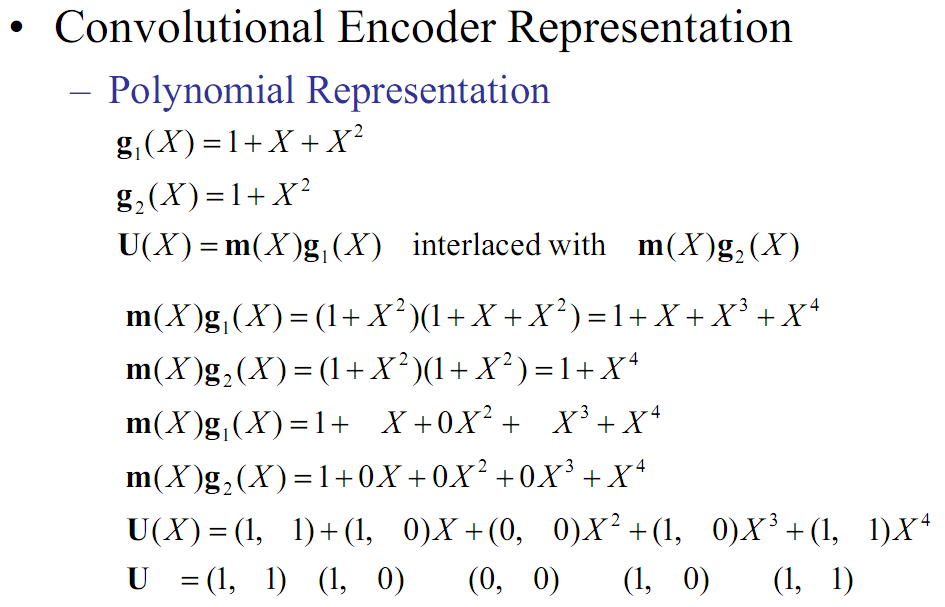

input m(X) = 1 0 1, K is 3(constraint length)

%{
n_out = 2; % 1 input 2 output 只与u的个数有关
K = 3; % constraint length
syms x;
g1X = 1+x+x^2 % g1(X)
g2X = 1+x^2 % g2(X)
m = [1 0 1]; % m(X)的系数，由低到高
mX = poly2sym(fliplr(m)) % 将m翻转变为由高到低, ploy2sym默认由高到低
u1X = mX*g1X
u1 = mod(fliplr(sym2poly(u1X)),2); % 将u1X翻转变为由低到高, ploy2sym默认由高到低
u2X = mX*g2X
u2 = mod(fliplr(sym2poly(u2X)),2); % 将u2X翻转变为由低到高, ploy2sym默认由高到低
u_out = zeros(K*2-1,n_out);
for i=1:K*2-1
    u_out(i,:) = [u1(i) u2(i)];
end
u_out
%}

EE609 hw7-1 coding

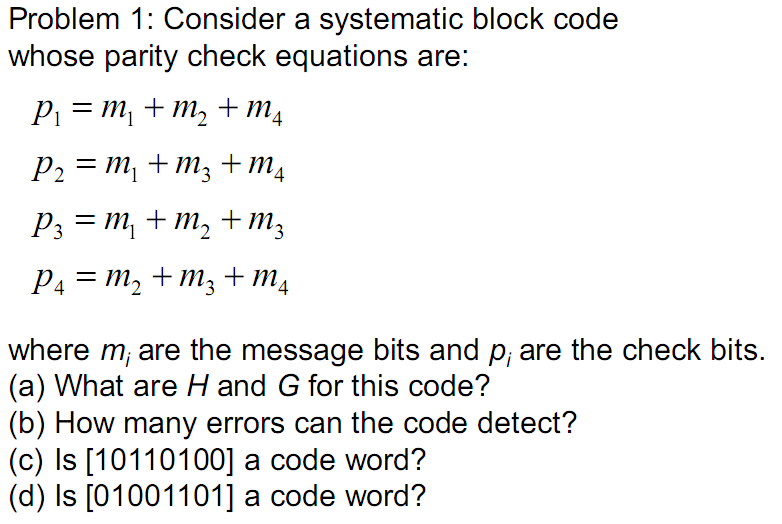

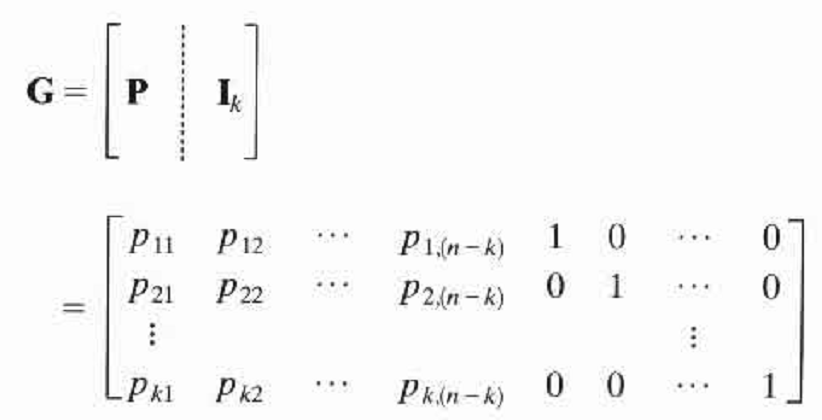

%{
n = 8;
k = 4;
P(:,1) = [1 1 0 1]; % the parity check bits P的个数=n-k，数组中元素代表的不是码中parity码的个数
P(:,2) = [1 0 1 1]; % the parity check bits
P(:,3) = [1 1 1 0]; % the parity check bits
P(:,4) = [0 1 1 1]; % the parity check bits
P
G = [P,eye(k)];
H = [eye(n-k),P.'];
d = zeros(length(G(:,1)));
for i = 1:length(G(:,1))
    for j = 1:length(G(:,1))
        d(i,j) = length(find(G(i,:)-G(j,:)));
        if d(i,j)==0
            d(i,j) = length(G(1,:));
        end
    end
end
dmin = min(min(d));
Ed = dmin-1; % Error detection
Ec = floor(Ed/2);% Error correcting

m = [1 1 0 1]; % the K-dimensional information vector
u = mod(m*G,2); % the N-dimensional code vector

% r = [1 0 1 1 0 1 0 0]; % received bit sequence
r = [0 1 0 0 1 1 0 1]; % received bit sequence

S = mod(r*H.',2); % a (N-K)-dimensional syndrome vector
%}

EE609 hw7-2 systematic form 特指循环编码

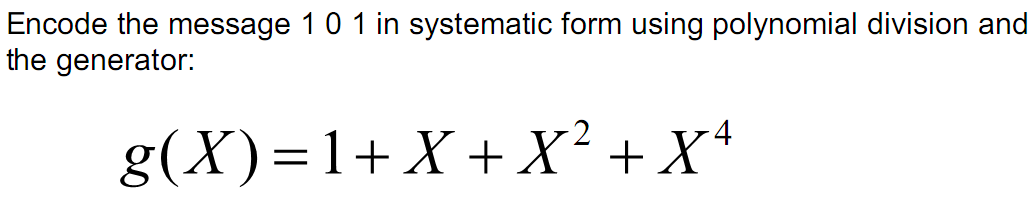

%{
% n = 7; % 传递码的个数
% k = 3; % 信息码的个数
syms x;
gX = 1+x+x^2+x^4 % g(X)
m = [1 0 1 ]; % m(X)的系数，由低到高
k = length(m); % 信息码的个数
mX = poly2sym(fliplr(m)) % 将m翻转变为由高到低, ploy2sym默认由高到低
n = length(sym2poly(expand(gX*mX))); % 传递码的个数，g(X)最高项同m(X)最高项乘积幂数+1
X_mX = expand(x^(n-k)*mX) % X^(n-k)*m(X)=q(X)g(X)+p(X)
coef_X_mX = sym2poly(X_mX);
coef_gX = sym2poly(gX);
[coef_q,coef_p]=deconv(coef_X_mX,coef_gX); %q是商，r是余数。数组从后到前表示从0次项到各高次项的系数
coef_qX = mod(coef_q,2);
coef_pX = mod(coef_p,2);
pX = poly2sym(coef_pX)
uX = X_mX+pX
u_out = mod(fliplr(sym2poly(uX)),2) % 输出序列，将u_out翻转变为由低到高, ploy2sym默认由高到低
%}

Shannon-hartley capacity theorem

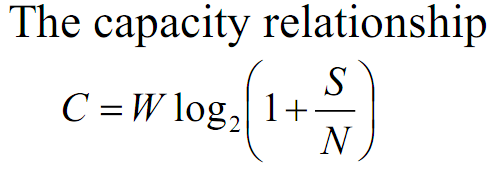

C = W*log2(1+S/N) =  W*log2(1+(Eb*R)/(N0*W))

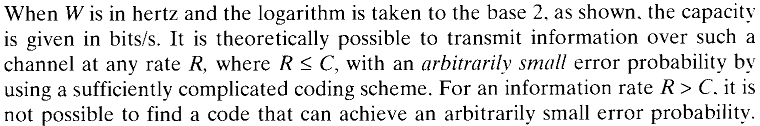

所以取C最大时是在R=C时

, set R=C

Shannon limits: C/W->0, Eb/N0=ln2=-1.6dB

Entropy

the average amount of information per source output:

Equivocation

the conditional entropy of the message of X, given Y: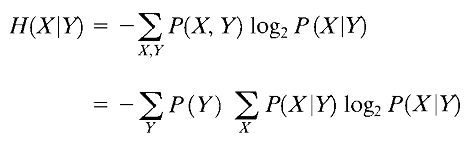

the average effective information content: 

the effective information bit rate: 

EE609 hw8-1 the average rate of information transmisson

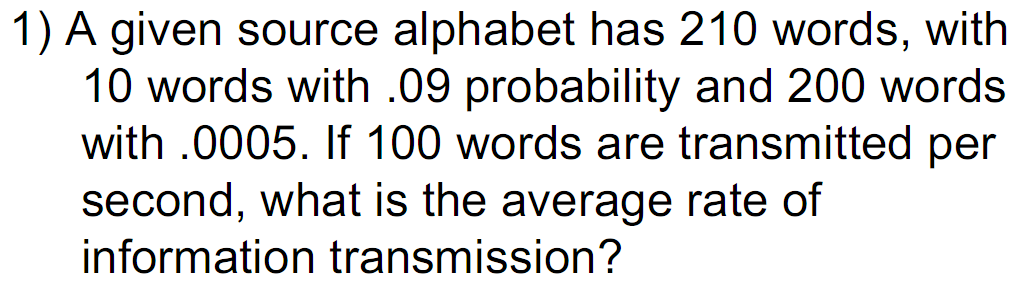

%{
R = 100; % words per second
n(1) = 10;
p(1) = 0.09;
n(2) = 200;
p(2) = 0.0005;
% n(3) = 8;
% p(3) = 0.02;
% n(4) = 9;
% p(4) = 0.01;
i = 2;
H = -n(1)*p(1)*log2(p(1)); % bits per words
while i<=length(p)
    H = H - n(i)*p(i)*log2(p(i));
    i = i+1;
end
R_ave = R*H; % bits per second
%}

bandwidth limited systems: MPSK,QAM

W = Rs, R/W = log2M bits/s/Hz

Pr/N0 = Eb/R/N0 = Es/Rs/N0

Pe = 2qfunc(sqrt(2*Es/N0)*sin(pi/M))

Pb = Pe/log2(M)

!!!P593: QAM can be considered a logical extention of QPSK. it can be viewed as a combination of amplitude shift keying(ASK) and phase shift keying(PSK).

, L = sqrt(M)

power limited systems: MFSK

W = MRs, R/W = (log2(M))/M bits/s/Hz

for noncoherent MFSK

Pe<=(M-1)/2*exp(-Es/(2*N0))

Pb = 2^(k-1)/(2^k-1)Pe

R/W>1, choose MPSK or QAM, R/W<1, choose MFSK

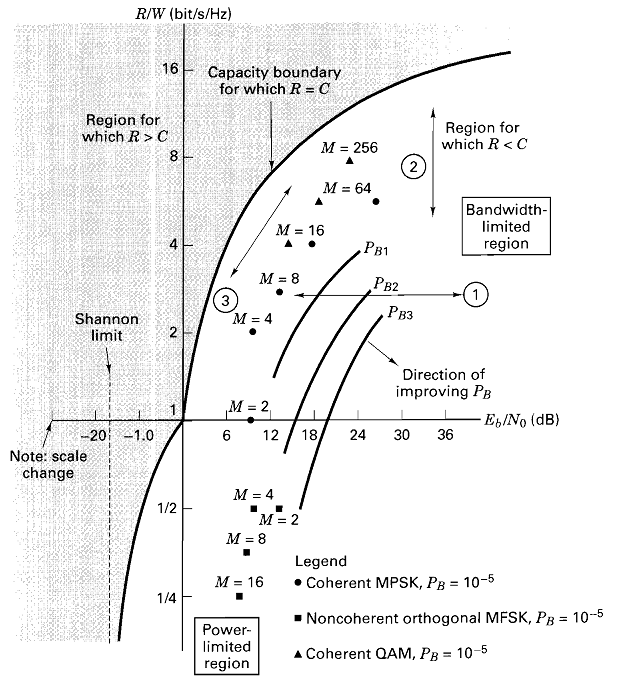

有限带宽系统(MPSK,QAM)，带宽利用率必须高， 然而随着M增加，所需能量也越来越大

有限能量系统(MFSK)，需尽可能减少能量，然而随着M增加，带宽利用率降低，消耗带宽增大

BDH(n,k,t), k represents the number of information or data bits that the codes transforms into n code bits, and t represents the largest number of incorrect channel bits that the code can correct within each n-size block

the channel bits rate Rc = (n/k)*R, the data bit rate

the symbol rate Rs = Rc/log2(M)

coding gain:

the decoded bit-error Pb:

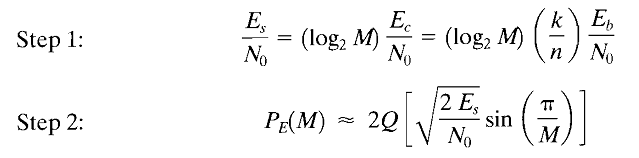

EE609 hw8-2 choose modulation and coding

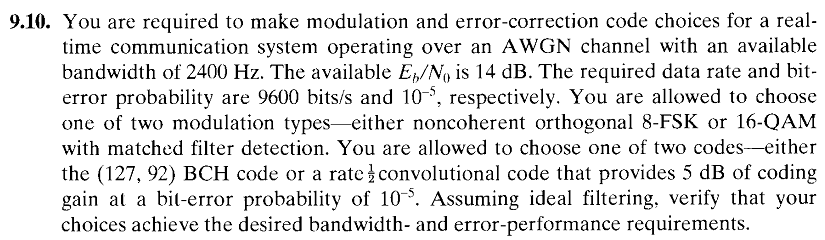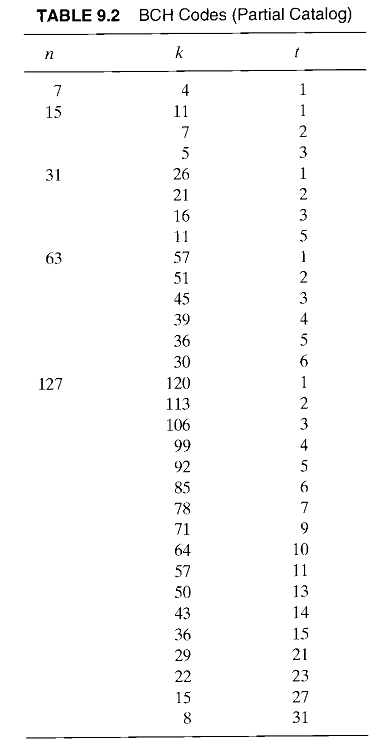

where Pb = 10^-2

%{
R = 9600; % bits/s, required
Pb_r = 10^-2; % required Pb
EbN0_db = 14;
W = 2400; % Hz
% M_PSK = 16; % the M of PSK
M_QAM = 16; % the M of QAM
M_FSK = 8; % the M of FSK
n = 127;
k = 92;
t = 5; % table 9.2
G_con_db = 5; % the gain of convolutional code
flag = zeros(1,3);

EbN0 = 10^(EbN0_db/10);
RW = R/W; % the bandwidth efficiency
% if RW==log2(M_PSK) % choose MPSK
%     k_PSK = log2(M_PSK);
%     EsN0_PSK = log2(M_PSK)*EbN0;
%     Pe_PSK = 2*qfunc(sqrt(2*EsN0_PSK)*sin(pi/M_PSK));
%     Pb_PSK = Pe_PSK/log2(M_PSK);
%     fprintf('Pb_PSK = %d\n',Pb_PSK);
%     Pb = Pb_PSK;
%     flag(1) = 'PSK';
% end
if RW==log2(M_QAM) % choose QAM
    k_QAM = log2(M_QAM);
    L = sqrt(M_QAM);
    Pb_QAM = 2*(1-L^-1)/log2(L)*qfunc(sqrt(3*log2(L)/(L^2-1)*2*EbN0));
    fprintf('Pb_QAM = %d\n',Pb_QAM);
    Pb = Pb_QAM;
    flag(2) = 'QAM';
end
if RW==log2(M_FSK)/M_FSK % choose MFSK
    k_FSK = log2(M_FSK);
    EsN0_FSK = log2(M_FSK)*EbN0;
    Pe_FSK = (M_FSK-1)/2*exp(-0.5*EsN0_FSK);
    Pb_FSK = 2^(k_FSK-1)/(2^k_FSK-1)*Pe_FSK;
    fprintf('Pb_FSK = %d\n',Pb_FSK);
    Pb = Pb_FSK;
    flag(3) = 'FSK';
end

if Pb_r >= Pb
    fprintf('%s do not need to coding!\n',flag);
end
if Pb_r<Pb % BCH coding
    syms cc
    if flag(1)=='PSK' % choose MPSK
        EsN0_PSK_BCH = log2(M_PSK)*(k/n)*EbN0;
        Pe_PSK_BCH = 2*qfunc(sqrt(2*EsN0_PSK_BCH)*sin(pi/M_PSK));
        Pc_PSK_BCH = Pe_PSK_BCH/log2(M_PSK);
        s = cc * nchoosek(n,cc)*Pc_PSK_BCH^cc*(1-Pc_PSK_BCH)^cc; % nchoosek(n,cc) C(cc,n) 求组合数
        Pb_PSK_BCH = 1/n*symsum(s, cc, t+1, n);
        fprintf('Pb_PSK_BCH = %d\n',Pb_PSK_BCH);
    end
    if flag(2)=='QAM' % choose QAM

Pbc = 每个正交载波上的误比特率        

Psc = 每个正交载波上的误符号率

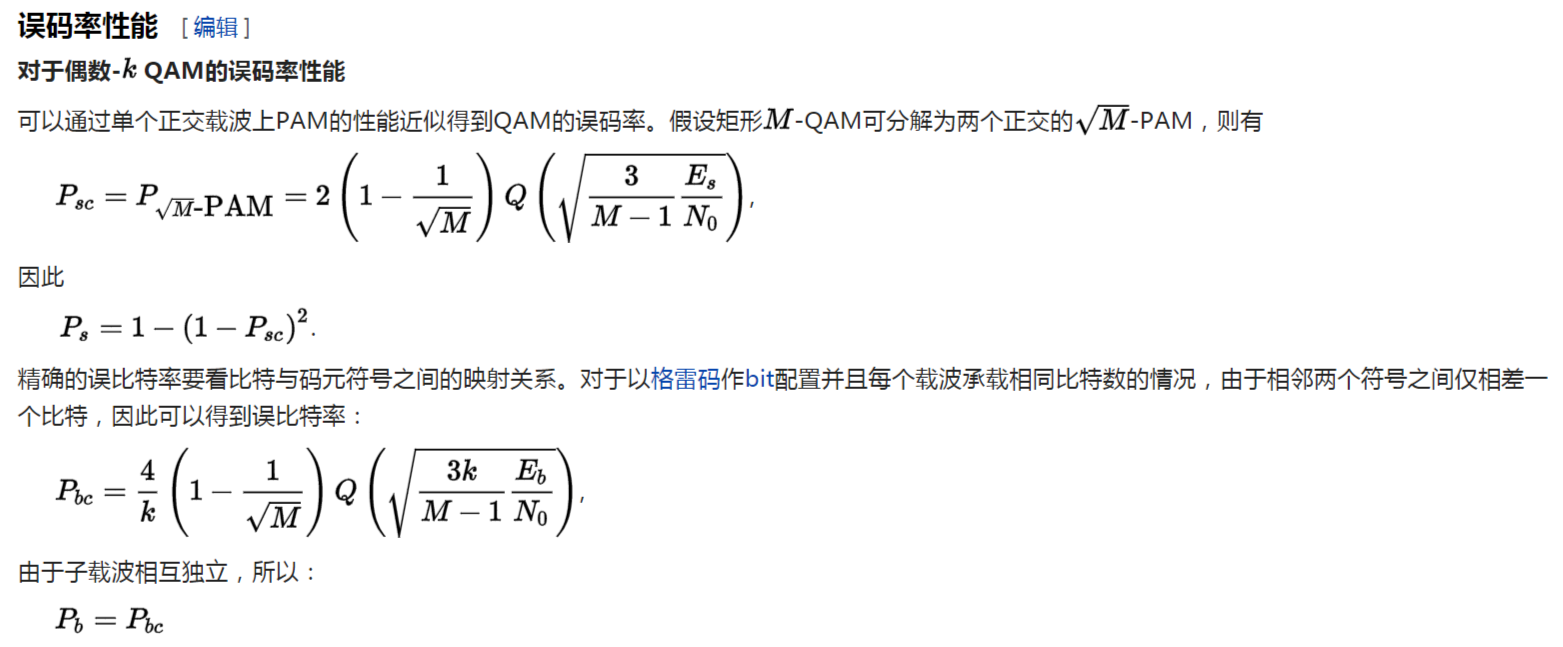

        EsN0_QAM_BCH = log2(M_QAM)*(k/n)*EbN0;
        Psc_QAM_BCH = 2*(1-L^-1)*qfunc(sqrt(3/(L^2-1)*EsN0_QAM_BCH));
        Ps_QAM_BCH = 1-(1-Psc_QAM_BCH)^2;
        Pc_QAM_BCH = 2/k_QAM*(1-sqrt(1-Ps_QAM_BCH));
        s = cc * nchoosek(n,cc)*Pc_QAM_BCH^cc*(1-Pc_QAM_BCH)^cc; % nchoosek(n,cc) C(cc,n) 求组合数
        Pb_QAM_BCH = 1/n*symsum(s, cc, t+1, n);
        fprintf('Pb_QAM_BCH = %d\n',Pb_QAM_BCH);
    end
    if flag(3)=='FSK' % choose FSK
        EsN0_FSK_BCH = log2(M_FSK)*(k/n)*EbN0;
        Pe_FSK_BCH = (M_FSK-1)/2*exp(-0.5*EsN0_FSK_BCH);
        Pc_FSK_BCH = 2^(k_FSK-1)/(2^k_FSK-1)*Pe_FSK_BCH;
        s = cc * nchoosek(n,cc)*Pc_FSK_BCH^cc*(1-Pc_FSK_BCH)^cc; % nchoosek(n,cc) C(cc,n) 求组合数
        Pb_FSK_BCH = 1/n*symsum(s, cc, t+1, n);
        fprintf('Pb_FSK_c = %d\n',Pb_FSK_c);
    end    
end
if Pb_r<Pb % convolutional coding
    EbN0_c = EbN0+10^(G_con_db/10);
    if flag(1)=='PSK' % choose MPSK
        EsN0_PSK_c = log2(M_PSK)*EbN0_c;
        Pe_PSK_c = 2*qfunc(sqrt(2*EsN0_PSK_c)*sin(pi/M_PSK));
        Pb_PSK_c = Pe_PSK_c/log2(M_PSK);
        fprintf('Pb_PSK_c = %d\n',Pb_PSK_c);
    end
    if flag(2)=='QAM' % choose QAM
        Pb_QAM_c = 2*(1-L^-1)/log2(L)*qfunc(sqrt(3*log2(L)/(L^2-1)*2*EbN0_c));
        fprintf('Pb_QAM_c = %d\n',Pb_QAM_c);
    end
    if flag(2)=='FSK' % choose FSK
        EsN0_FSK_c = log2(M_FSK)*EbN0_c;
        Pe_FSK_c = (M_FSK-1)/2*exp(-0.5*EsN0_FSK_c);
        Pb_FSK_c = 2^(k_FSK-1)/(2^k_FSK-1)*Pe_FSK_c;
        fprintf('Pb_FSK_c = %d\n',Pb_FSK_c);
    end
end
%}

EE609 hw8-3 choose modulation and coding

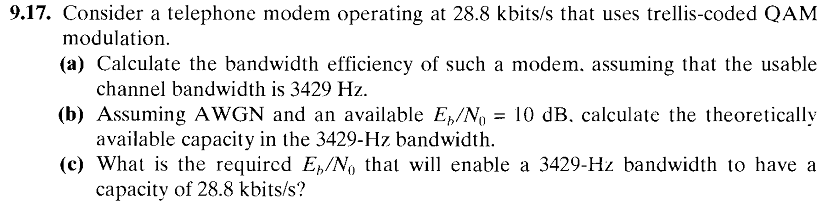

where the usable channel bandwidth is 6kHz rather than 3429 Hz.

%{
R = 28.8e3; % bits/s
W = 6e3; % Hz
RW = R/W;

EbN0_db = 10; % db
EbN0 = 10^(EbN0_db/10);
C = W*log2(1+EbN0*RW); % C should >=R
syms C_max real;
C_max = solve(W/C_max*(2^(C_max/W)-1) == EbN0,C_max); % C_max when C=R
C_max = double(C_max);

syms EbN0_r C real;
EbN0_r = solve(C == W*log2(1+EbN0_r*C/W),EbN0_r);
EbN0_r=subs(EbN0_r,C,28.8e3);
EbN0_r = double(EbN0_r);
EbN0_r_db = db(EbN0_r,'p');
%}